# Ordinary Differential Equation (ODE) solvers

## Introduction

The [ODE solvers](https://au.mathworks.com/help/matlab/ordinary-differential-equations.html) in MATLAB solve initial value problems with a variety of properties. In this activity we will learn how to use the most common ODE solver to solve first and second order ODEs.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully.

- Run the code within a section before starting to read the next. 

- To run the code from each section, *click into the code section* and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

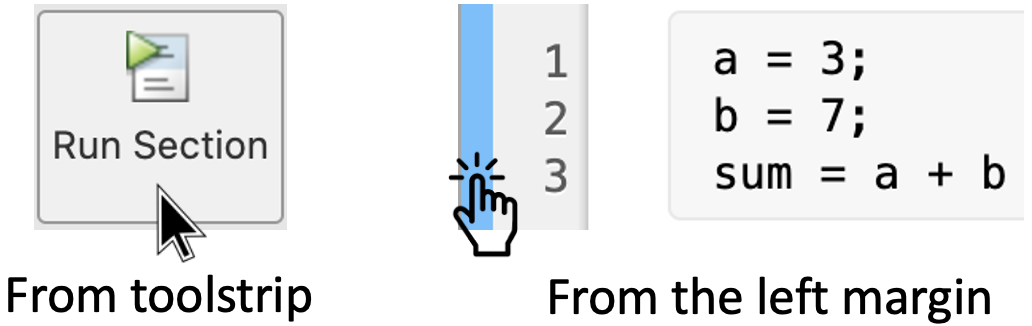

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Basic implementation

In order to solve an Initial Value Problem (IVP) in MATLAB we can use the following MATLAB code:

[`[t,y] = ode45(odefun, tspan, y0)`](https://au.mathworks.com/help/matlab/ref/ode45.html#d123e1004390)

where 

- `[t,y]:` Defines two column vectors to store values of $t$ and $y(t)$. Each row in the solution array `y` corresponds to a value at the time given by the same row in `t`.

- `odefun`: [Ordinary differential equation function](https://au.mathworks.com/help/matlab/ref/ode45.html#bu00_4l_sep_shared-odefun)

- `tspan`: [Interval of integration](https://au.mathworks.com/help/matlab/ref/ode45.html#bu00_4l_sep_shared-tspan)

- `y0`: [Initial conditions](https://au.mathworks.com/help/matlab/ref/ode45.html#bu00_4l_sep_shared-y0)

- ode45: [MATLAB function to solve ODEs](https://au.mathworks.com/help/matlab/ref/ode45.html#d123e1004390)

**Remark:** In MATLAB there are several ODE solvers that we could use (e.g. `ode23`, `ode113,` `ode23s`, `ode23t`, and `ode23tb`). However, in the following activities we will use only the solver `ode45`. You can learn more details about these commands here [Choose an ODE Solver](https://au.mathworks.com/help/matlab/math/choose-an-ode-solver.html), which provides general guidelines on when to use each of the different solvers.

For example, consider the IVP problem

$\frac{dy}{dt}=f(t,y)$, $y(0)=1$, $0\leq t\leq 2$,

where $f(t,y) = 1-e^{-4t}-2y$.

We can define $f(t,y)$ as an anonymous function:

f = @(t,y) 1 - exp(-4*t) - 2*y;

Then we solve the IVP with the command `ode45`:

[t,y] = ode45(f, [0 2], 1);

Finally we plot the solution:

plot(t, y,'r-', t, y, 'b+')

How would you change these commands to solve the IVP for the same ODE but with the condition $y(1)=1$ on the interval $1\leq t\leq3$? Try it and re-run this section to see the result.

## 2. Plotting solutions of IVP problems and slope fields

Consider now the following IVP

$\frac{dy}{dt}=g(t,y)$, $y(1)=0.1$,  $1\leq t\leq 2$

where $g(t,y) = 2te^{-1/t}+y/t^2$.

We can use the previous method to plot a numerically approximated solution to the IVP over the top of a slope field.

First, we need defined the ODE and use the command `ode45`:

g = @(t,y) 2*t*exp(-1/t) + y/t^2;
[gt, gy] = ode45(g, [1 2], 0.1);

Then we plot the slope field including the approximated solution. Run this section to see the result:

% Interval bounds
tmin =1;
tmax =2;
ymin=0;
ymax=2;
% Grid spacing
spacing = 0.15;
 
% Define x and y coordinates
[pt, py] = meshgrid(tmin:spacing:tmax,ymin:spacing:ymax);
 
% Calculate slopes
ydash = 2*pt.*exp(-1./pt)+py./pt.^2;
 
% Define slope vector components
dt = (spacing/2)./sqrt(1+ydash.^2);
dy = (spacing/2)*ydash./sqrt(1+ydash.^2);
 
% Clear the figure
clf;
 
% Create slope field
q = quiver(pt, py, dt, dy,'b','AutoScale','off');
set(q,'ShowArrowHead','off','LineWidth',1)

% Include approximated solution
hold on

plot(gt, gy,'r-', gt, gy, 'k+')

hold off
 
% Set axis and labels
axis([tmin tmax ymin ymax])
xlabel('x')
ylabel('y')

**Note:** In the previous code we used the command `set()` to set graphics object properties. For more details see: [Set Graphics Object](https://au.mathworks.com/help/matlab/ref/set.html).

## 3. Systems of differential equations

Anonymous function can also be used to define systems of ODEs. The easiest way to think of this is that the function will take a vector of inputs $Y$ and puts the inputs into a vector of equations.

For example, a second order ODE of the form


$$z''+z'-z=\cos(t)\qquad \qquad (1)$$


can be expressed as the coupled system of equations. Let $z'=y$. Then we have that $z''=y'$. If we substitute in equation (1) we obtain the system:


$$\begin{array}{ll}
z'=y\\
y'=-y+z+\cos(t)
\end{array}$$


Define the vector $Y$ as 


$$Y = \left(\begin{array}{c}
z\\
y
\end{array}
\right)$$


The derivative of $Y$ is a vector whose entries correspond to the coupled equations:


$$Y' = \left(\begin{array}{cc}
z'\\
y'
\end{array}
\right)
=\left(\begin{array}{c}
y\\
-y+z+\cos(t)
\end{array}
\right)
$$


Now we have two first order equations that we can store as a vector of anonymous functions with vector input Y. We do this by writting:

### 3.1 Numerical solution of systems of ODEs

Now consider the IVP

$z''+z'-z=\cos(t)$, $z(0)=1$, $z'(0)=2$, $0\leq t\leq 10$.

which can be re-written as

$\begin{array}{ll}
z'=y\\
y'=-y+z+\cos(t)
\end{array}$ , $z(0)=1$, $z'(0)=2$, $0\leq t\leq 10$.

To find and plot a numerical solution of this system over the interval  $0\leq t\leq 10$, first we define the initial and final time; and the initial conditions at $0$:

t0 = 0;   % Initial time
tf = 10;  % Final time, here we have chosen 10
z0 = 1;   % Initial condition z(0)=1
y0 = 2;   % Initial condition z'(0)=2

The anonymous function representing the system is then defined as:

secODE = @(t,Y) [Y(2); -Y(2)+Y(1)+cos(t)];

Now, we solve and plot the solution:

[T,Y] = ode45(secODE, [t0 tf], [z0; y0]);
plot(T,Y(:,1),'ro-');

Run this section to see the result. Change the initial conditions of the IVP, or modify the equation of the system. Re-run this section to see the new output.

**Remark:** Since we solved a coupled system of 2 equations there are 2 columns in `Y`. The first column `Y(:,1)` gives the values of $z(t)$, while the second column gives the values of $y(t)$.

Finally, if we wish to compute the approximate value for $z$ at $t=10$, we just need to use the command 

Y(end,1)

Run this section to see the output. The result should be approximately 879.

## 4. Hands on Practice

Let's practice what we just learned.

#### Activity 1

Consider the following IVP

$\frac{dy}{dt}=te^{\sin(t)}-y\cos t$, $y(0)=1$  $0\leq t\leq 4$.

- Plot a numerically approximated solution to the IVP over the top of a slope field.

- Estimate the value of $y(4)$.

Write your code here:

#### Activity 2

The figure below shows a pendulum with length $L$ and the angle $\theta$ for the vertical to the pendulum.

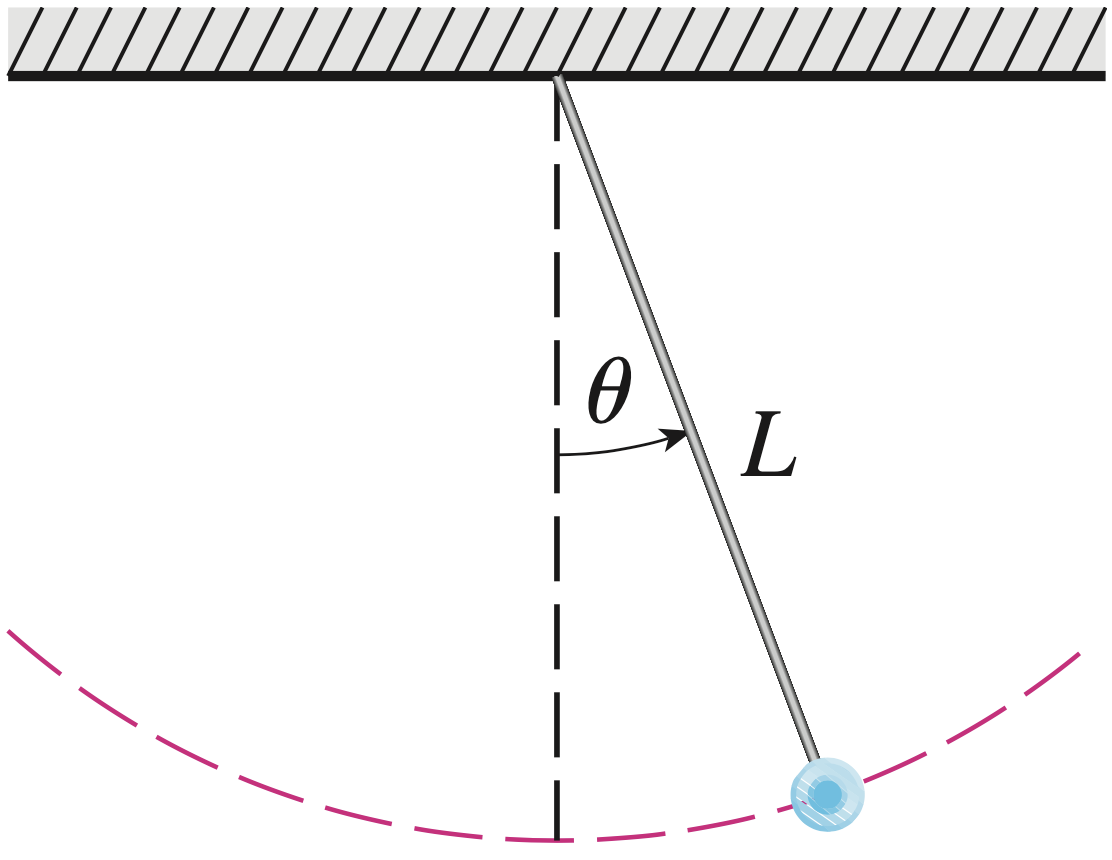

The motion of this pendulum is determined by the $\theta$ as a function of time, which satisfies the nonlinear differential equation


$$\frac{d^2\theta}{dt^2}+\frac{g}{L} \sin\theta =0$$


where $g$ is the acceleration due to gravity.

In your notebook, re-write this second order ODE as a system of differential equations. Then compute an approximated solution to the IVP

$\frac{d^2\theta}{dt^2}+\frac{9.81}{2} \sin\theta =0$, $\theta(0)=3\pi/4$, $\theta'(0)=0$, $0\leq t\leq 5$.

Write your code here: